# Quadcopter Basics - Movement

Load up parameters for quadcopter.

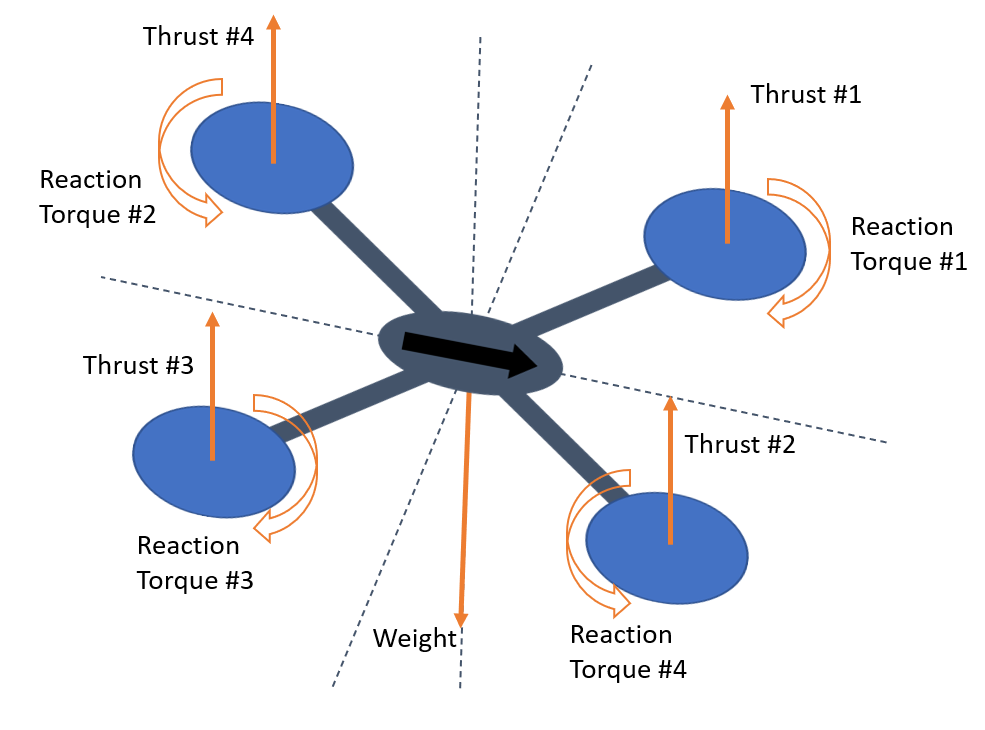

load quad_params.mat

## Quadcopter Simulation

In order to model the movement of the quadcopter, we have to solve at least two sets of equations at every timestep in a simulation. Firstly, we compute the total forces and moments as a result of the propeller speeds, as described in the previous script ([Quadcopter Basics](matlab:open('./quadcopterBasics.mlx'))). 

Secondly, we need to apply those thrust forces and moment in a direction where the quadcopter is currently oriented. This requires us to use rotation matrices, as described in [SixDoFMatrix](matlab:open('./SixDoFMatrix.mlx')).

An easier way is do all this in Simulink where all we need to do is generate the propeller speeds, and later on, the control signals. Let's try hovering first.

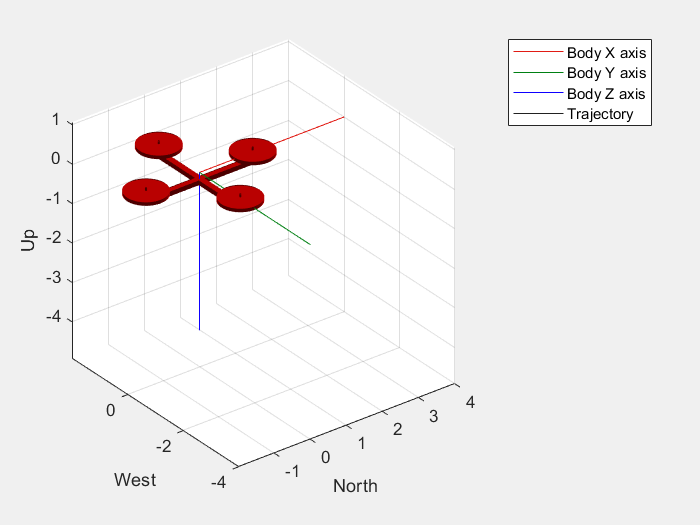

ans =   Simulink.SimulationOutput:

                   tout: [301x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


w = [4000 4000 4000 4000];

% open('uav_sim.slx');

sim('uav_sim.slx')

If all the forces are balanced, the Quadcopter shouldn't move.

### Quadcopter Movement - Elevation

Adjusting elevation for a quadcopter is relatively simple. By increasing or decreasing the thrust of all propellers (relative to the weight), an upward or downward acceleration can be induced which leads to a change in elevation.

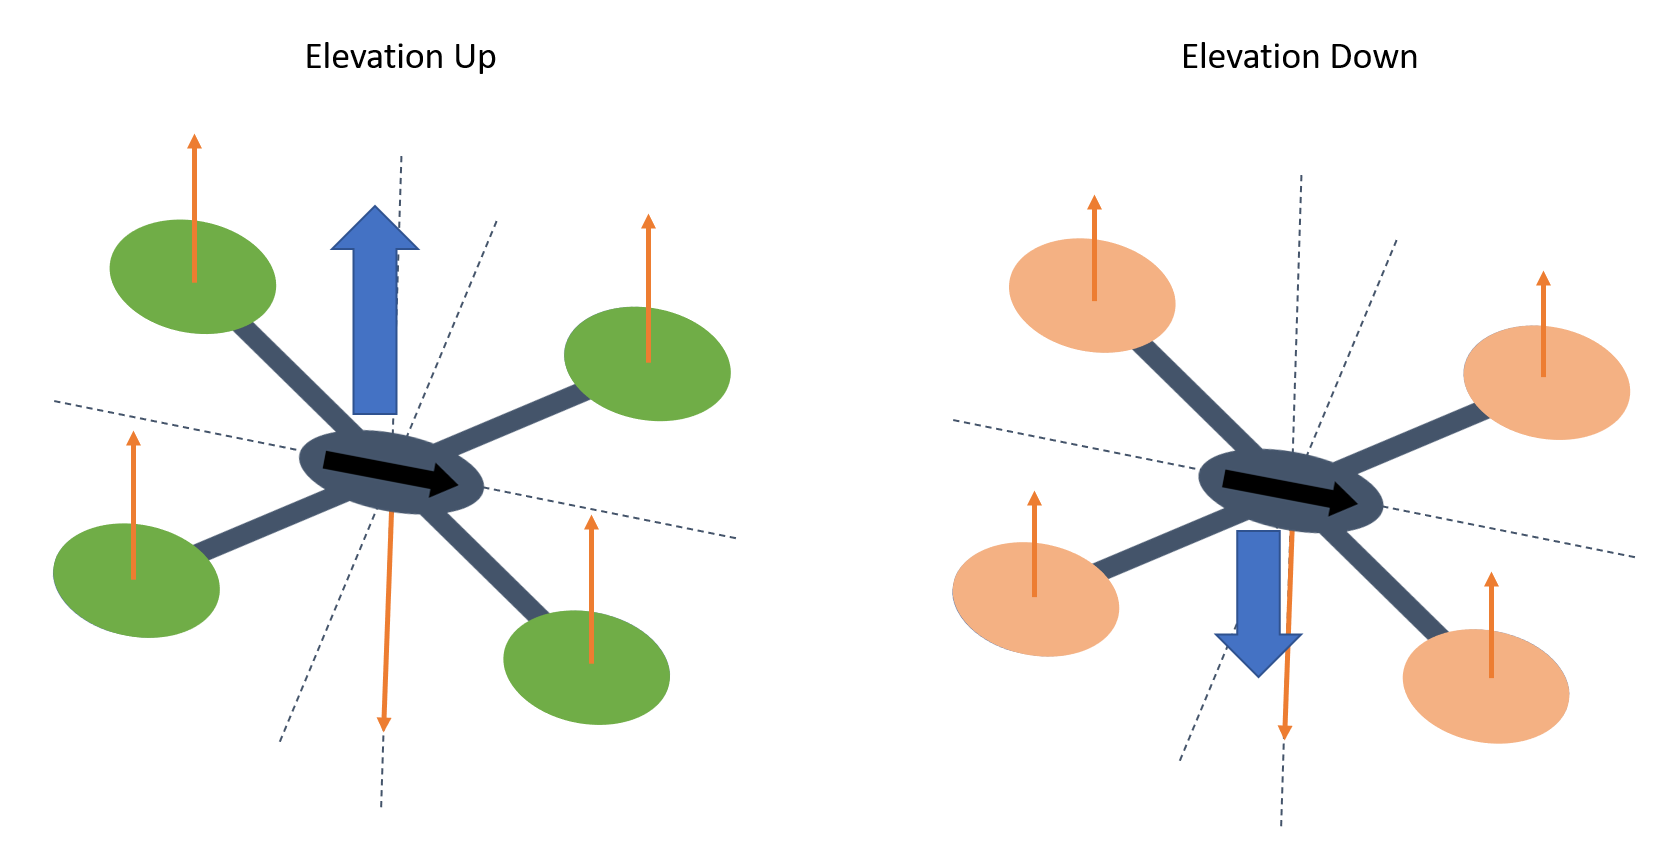

Next, let try changing the elevation by turning all the propellers up or down. We can see the UAV drops down or rises up vertically, as all the propellers are balanced.

speed = 4250;
w = [speed speed speed speed];
sim('uav_sim.slx')

ans =   Simulink.SimulationOutput:

                   tout: [307x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### Quadcopter Movement - Pitch and Movement

In order to move forward, the speed of the front two propellers can be reduced relative to the two rear propellers, which causes the quadcopter to pitch forward. Once the angle has changed, all the propellers are turned at the same speed, which should sufficient to counteract the weight force. 

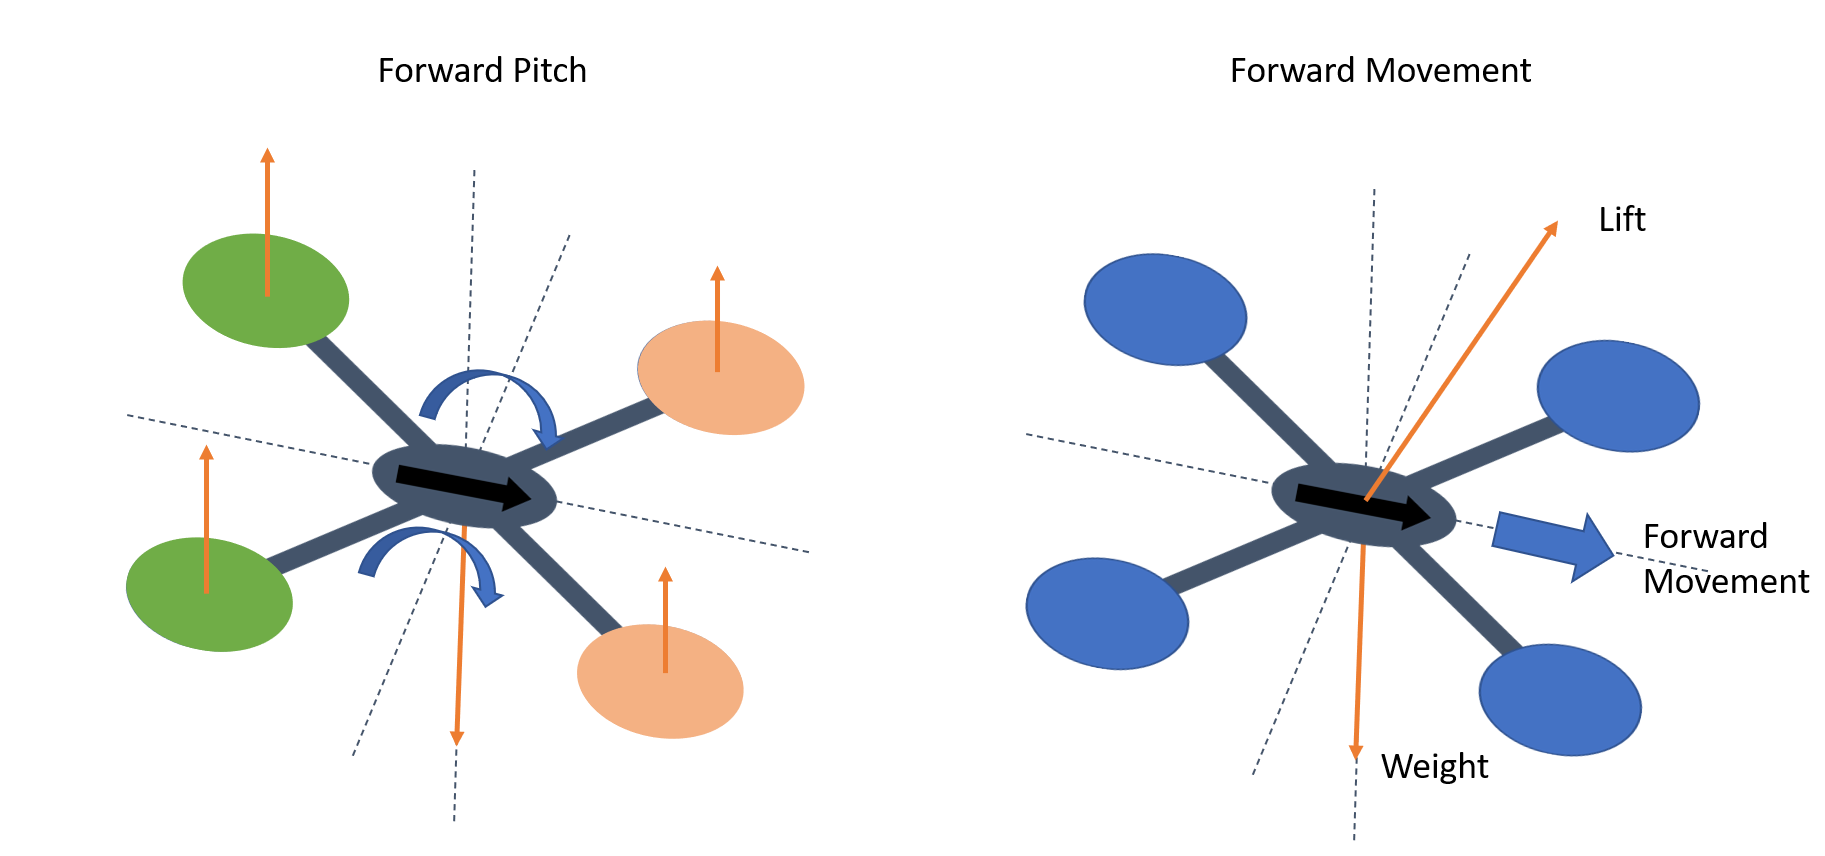

The total lift component of the thrust now points slight forward of the vertical axis, inducing forward movement. Reverse movement can similarly be achieved by pitching backwards. The mathematics and controls are exactly the same, just with a negative sign.

w = [4000;4000;4100;4100]

w =         4000
        4000
        4100
        4100


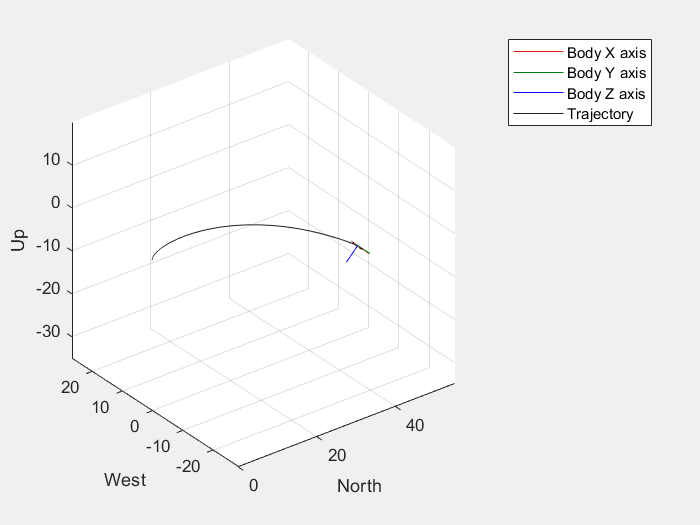

ans =   Simulink.SimulationOutput:

                   tout: [307x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim('uav_sim.slx')

We can see that at larger values or longer runtimes, the drone tips over and goes unstable, which is why we need to implement feedback controllers to maintain the orientation. We will see this in future lectures.

### Quadcopter Movement - Roll and Lateral

Similar to the forward/backward movement, the speed of two propellers on the same side can be reduced, which causes quadcopter to roll left/right. Once the angle has changed, all the propellers are turned at the same speed, which should sufficient to counteract the weight force. The total lift component of the thrust now points slight left or right of the vertical axis, inducing lateral movement.

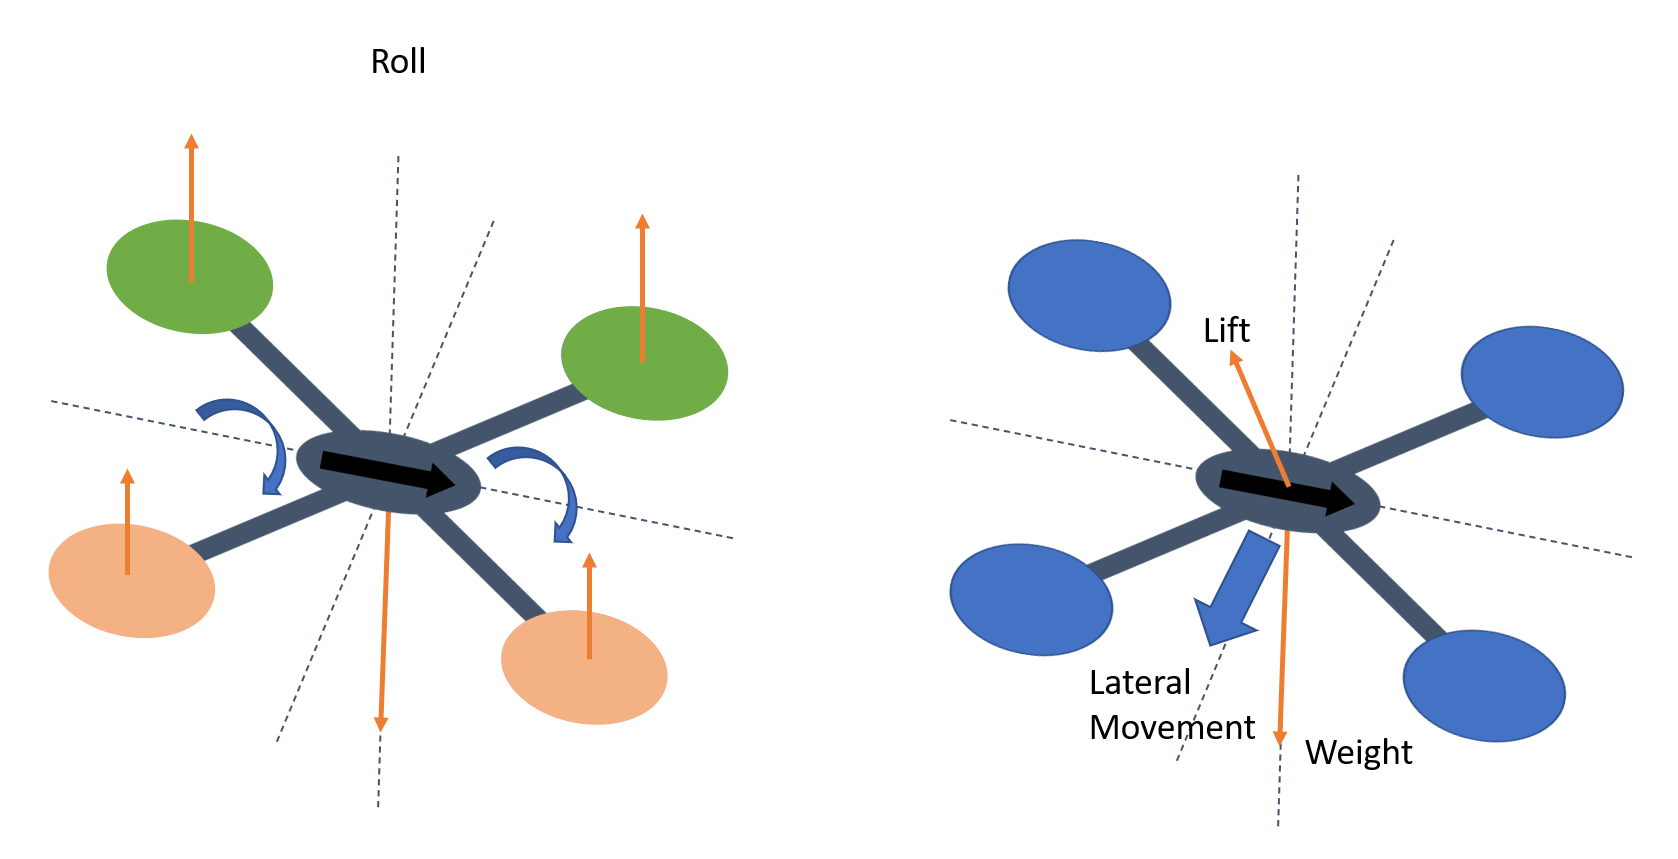

w = [4250 3900 3900 4250]

w =         4250        3900        3900        4250


sim('uav_sim.slx')

ans =   Simulink.SimulationOutput:

                   tout: [304x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### Quadcopter Movement - Yaw 

The quadcopter can be rotated left or right relative to the vertical axis by changing the speeds of opposite propellers. If one set is sped up, while the other slows down, it creates an imbalance in the reaction moments while still preserving the total thrust force. This can induce a rotation, which can be used to steer the quadcopter.

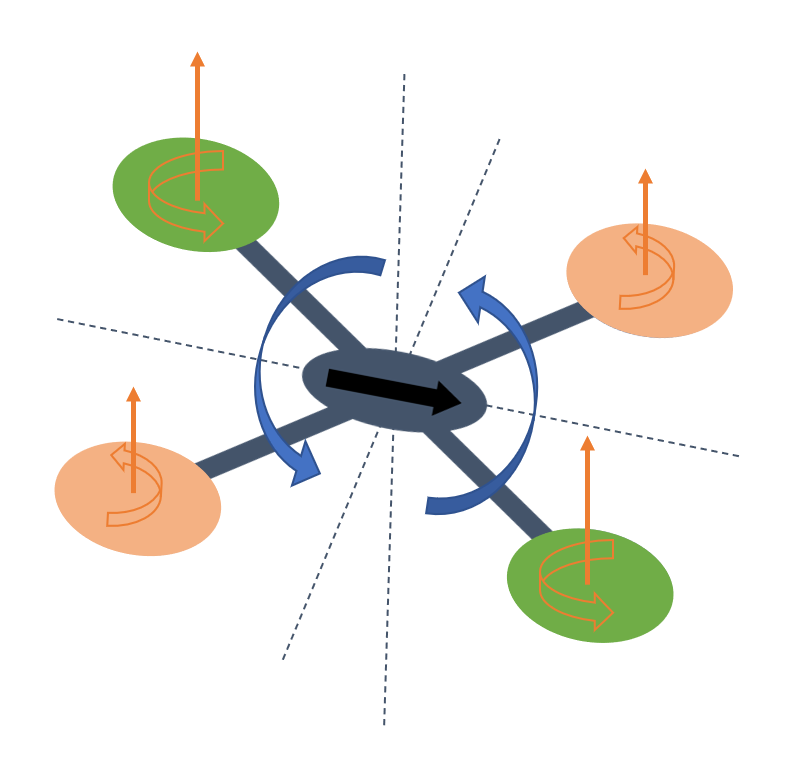

w = [3700 4500 4500 3700]

w =         3700        4500        4500        3700


sim('uav_sim.slx')

ans =   Simulink.SimulationOutput:

                   tout: [304x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### Next Steps

As we can see in the simulations, while getting an open-loop response is possible, we need to develop better feedback controllers to ensure system stability and reliably follow a desired trajectory. Let's see the basics of feedback control in the next section, and then implement a controller for the quadcopter.

Copyright © MathWorks Inc. 2022